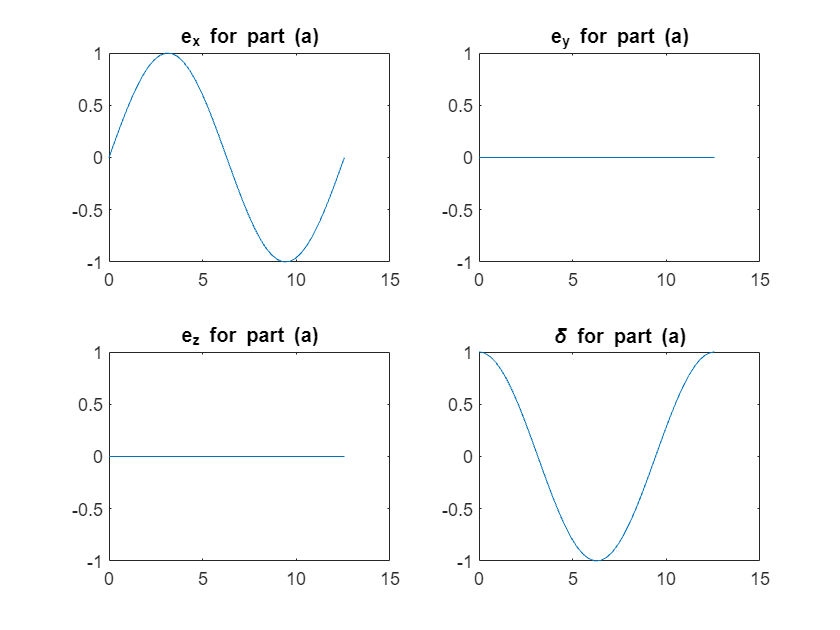

% Define the initial conditions
e = [0; 0; 0]; % e vector (zero for part a)
delta = 1;     % δ scalar part of quaternion (1 for part a)

% q = quaternion(delta, e(1), e(2), e(3))
% [a, b, c, d] = parts(q)


% Define the body rates for part (a) and (b)
omega_a = [1; 0; 0]; % Positive roll rate for part (a)
omega_b = [0; 0; 1]; % Positive yaw rate for part (b)

% Time span for the simulation
t_span = [0 2*2*pi]; % Two complete revolutions


% ^b \omega = [p;q;r]
% ^b \omega_skew = [0 -r q; r 0 -p; -q p 0]

% Quaternion derivative function for part (a)
% quaternion_derivative_a = @(t, q) [
%     0.5 * q(4) * q(1:3) - 0.5 * omega_a' * q(1:3) * q(4);
%     -0.5 * omega_a' * q(1:3);
% ];
quaternion_derivative_a = @(t, q) [
    eq_e(omega_a, q);
    eq_delta(omega_a, q)
];

% Quaternion derivative function for part (b)
quaternion_derivative_b = @(t, q) [
    eq_e(omega_b, q);
    eq_delta(omega_b, q)
];

% Solve the ODE for part (a)
[time_a, q_a] = ode45(quaternion_derivative_a, t_span, [e; delta]);

% Solve the ODE for part (b)
% For part (b), we need to set the initial condition for e3 = -1 (upside down)
[time_b, q_b] = ode45(quaternion_derivative_b, t_span, [0; 0; -1; 0]);

% Plot the results for part (a)
figure;
subplot(2,2,1);
plot(time_a, q_a(:,1)); title('e_x for part (a)');
subplot(2,2,2);
plot(time_a, q_a(:,2)); title('e_y for part (a)');
subplot(2,2,3);
plot(time_a, q_a(:,3)); title('e_z for part (a)');
subplot(2,2,4);
plot(time_a, q_a(:,4)); title('\delta for part (a)');

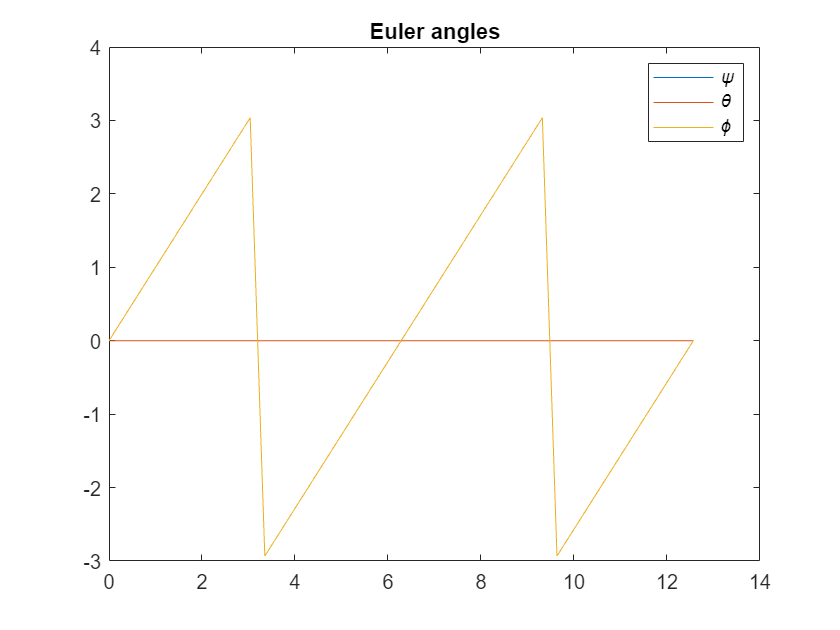

quat_result_a = quaternion(q_a(:,4), q_a(:,1), q_a(:,2), q_a(:,3));
euler_result_a = quat2eul(quat_result_a, "ZYX");

figure;
plot(time_a, euler_result_a);
title('Euler angles');
legend('\psi', '\theta', '\phi');

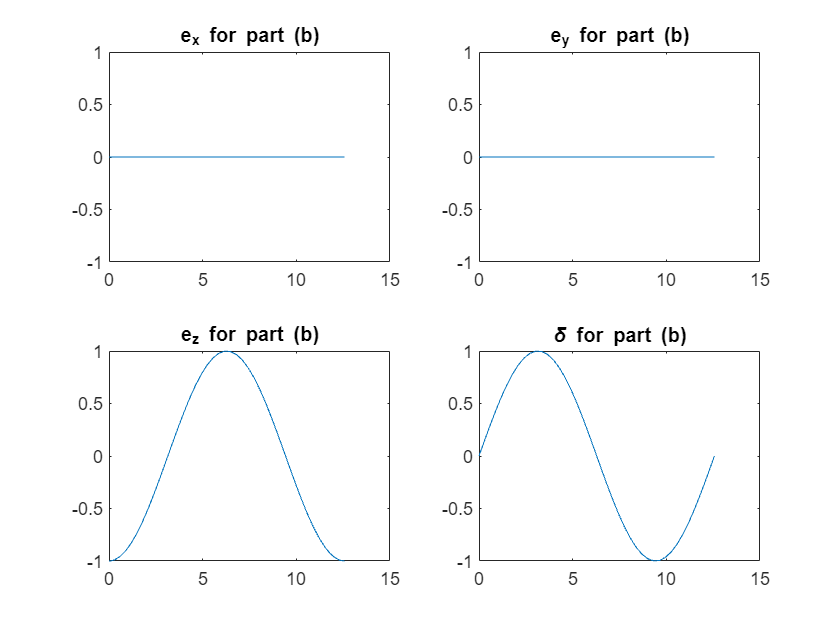

% Plot the results for part (b)
figure;
subplot(2,2,1);
plot(time_b, q_b(:,1)); title('e_x for part (b)');
subplot(2,2,2);
plot(time_b, q_b(:,2)); title('e_y for part (b)');
subplot(2,2,3);
plot(time_b, q_b(:,3)); title('e_z for part (b)');
subplot(2,2,4);
plot(time_b, q_b(:,4)); title('\delta for part (b)');

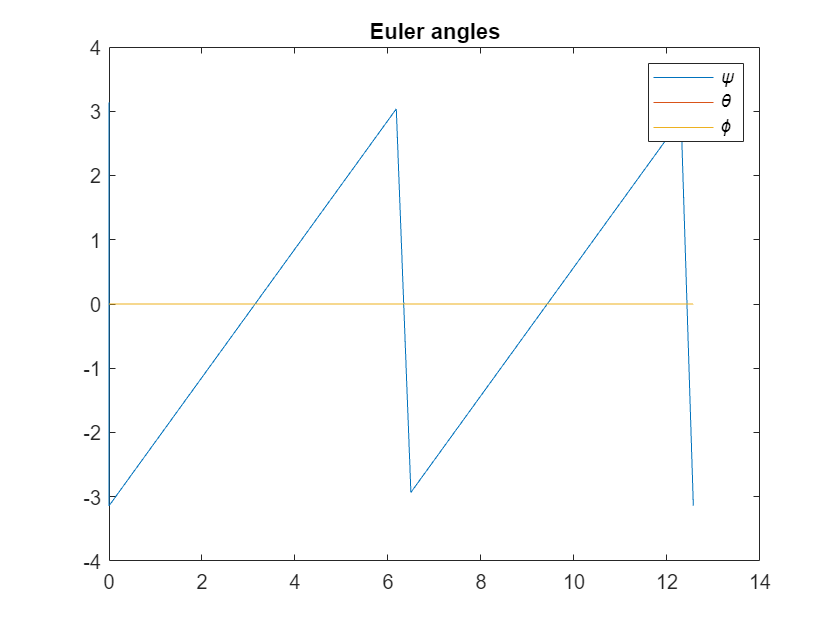

quat_result_b = quaternion(q_b(:,4), q_b(:,1), q_b(:,2), q_b(:,3));
euler_result_b = quat2eul(quat_result_b, "ZYX");

figure;
plot(time_b, euler_result_b);
title('Euler angles');
legend('\psi', '\theta', '\phi');

The difference between $\frac{^B d\vec{e}}{dt}$ and $\frac{^E d\vec{e}}{dt}$ is caused by the flip. After flipped along the roll axis for 180deg, the body pitch and yaw axises point at the opposite directions of the original earth axises. So the second and third element of  $\frac{^B d\vec{e}}{dt}$ will be the opposite numbers of $\frac{^E d\vec{e}}{dt}$.

function e_dot = eq_e(omega, q)
    delta = q(4);
    e = q(1:3);
    e_dot = 0.5 * delta * omega - 0.5 * skewSymmetric(omega) * e;
end

function delta_dot = eq_delta(omega, q)
    e = q(1:3);
    delta_dot = -0.5 * omega' * e;
end

function v_skew = skewSymmetric(v)
    v_skew = [0, -v(3), v(2); v(3), 0, -v(1); -v(2), v(1), 0];
end